clear
close all

## Variables and Data

% import data from men's 73 kg weight class
data = csvread('class73.csv');

sex                         = data(:,1);  % sex
age                         = data(:,2);  % age
bweight                     = data(:,3);  % body weight
snatch_firstAttempt         = data(:,4);  % declared snatch weight
snatch_firstSuccess         = data(:,5);  % first successful snatch weight
snatch_max                  = data(:,6);  % max snatch weight
snatch_max2declared         = data(:,7);  % delta between max and declared
snatch_max2firstSuccess     = data(:,8);  % delta between first success and max
cj_firstAttempt             = data(:,9);  % declared clean-jerk weight
cj_firstSuccess             = data(:,10);  % first successful clean-jerk weight
cj_max                      = data(:,11); % max clean-jerk weight
cj_max2declared             = data(:,12); % delta between max and declared
cj_max2firstSuccess         = data(:,13); % delta between first success and max
total                       = data(:,14); % total max weight "score"

## Derived Metrics

% Snatch max to CJ max ratio
snatch_ratio = snatch_max./cj_max;
% Sum of deltas between declared and max across both events
total_deltas = cj_max2declared + snatch_max2declared;

## Initial Model - age, body weight, snatch ratio, deltas

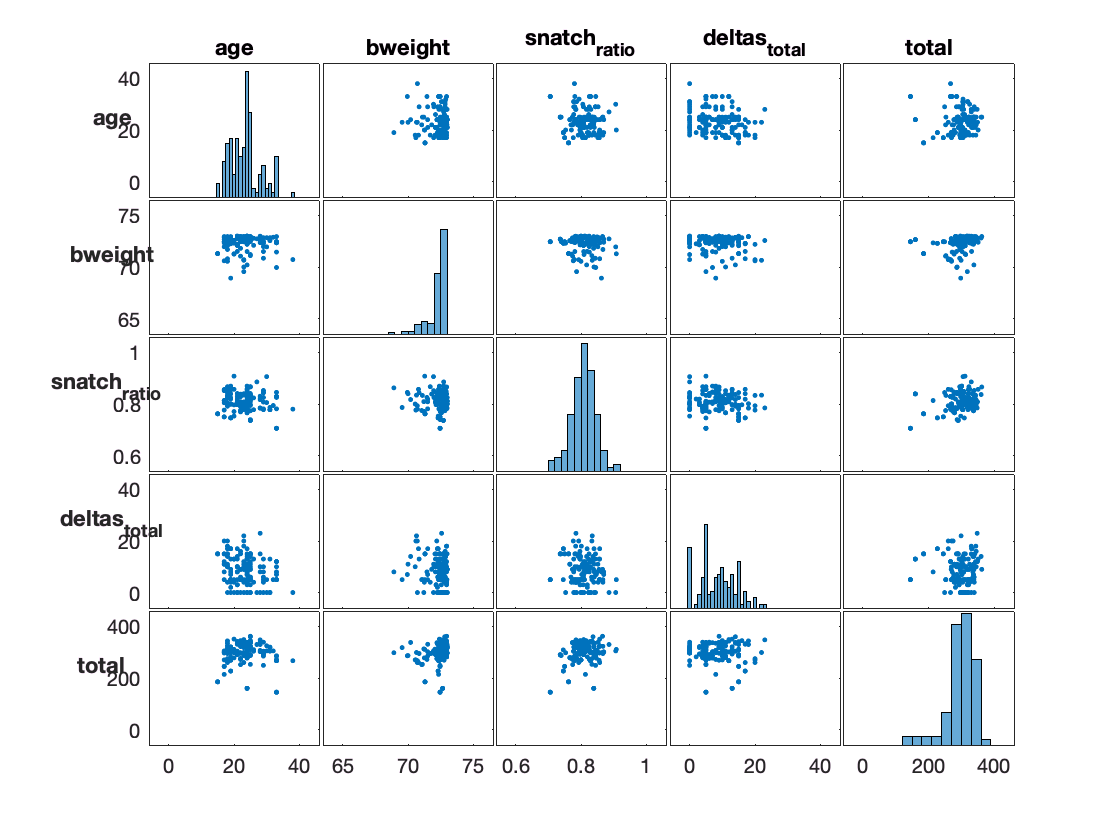

dm = [age, bweight, snatch_ratio, total_deltas, total];

labels = {...
    'age',...
    'bweight',...
    'snatch_{ratio}',...
    'deltas_{total}',...
    'total'...
    };

% Create the plot matrix
[~,ax] = plotmatrix(dm);
for i = 1:length(labels)
  title(ax(1,i), labels{i})
  yl = ylabel(ax(i,1),labels{i},'fontweight','bold','Rotation', 0);
  yl.Position(1) = yl.Position(1) - 3.0;
end


mdl1 = fitlm([age, bweight, snatch_ratio, total_deltas],total,'VarNames',{'age' 'bweight','snatch_max/cj_max','total_deltas','total'})

mdl1 = 
Linear regression model:
    total ~ 1 + age + bweight + snatch_max/cj_max + total_deltas

Estimated Coefficients:
                         Estimate       SE         tStat        pValue  
                         _________    _______    _________    __________

    (Intercept)            -1173.8     330.19      -3.5551    0.00050869
    age                  -0.028664    0.73825    -0.038827       0.96908
    bweight                   15.3     4.3235       3.5388    0.00053846
    snatch_max/cj_max          450     89.965        5.002     1.597e-06
    total_deltas          0.064145    0.62528      0.10259       0.91843


Number of observations: 152, Error degrees of freedom: 147
Root Mean Squared Error: 39.7
R-squared: 0.194,  Adjusted R-Squared 0.172
F-statist

## Initial Findings:

Age and total deltas are not statistically significant. Revised model will exclude these two variables.

## Auxiliary Plots

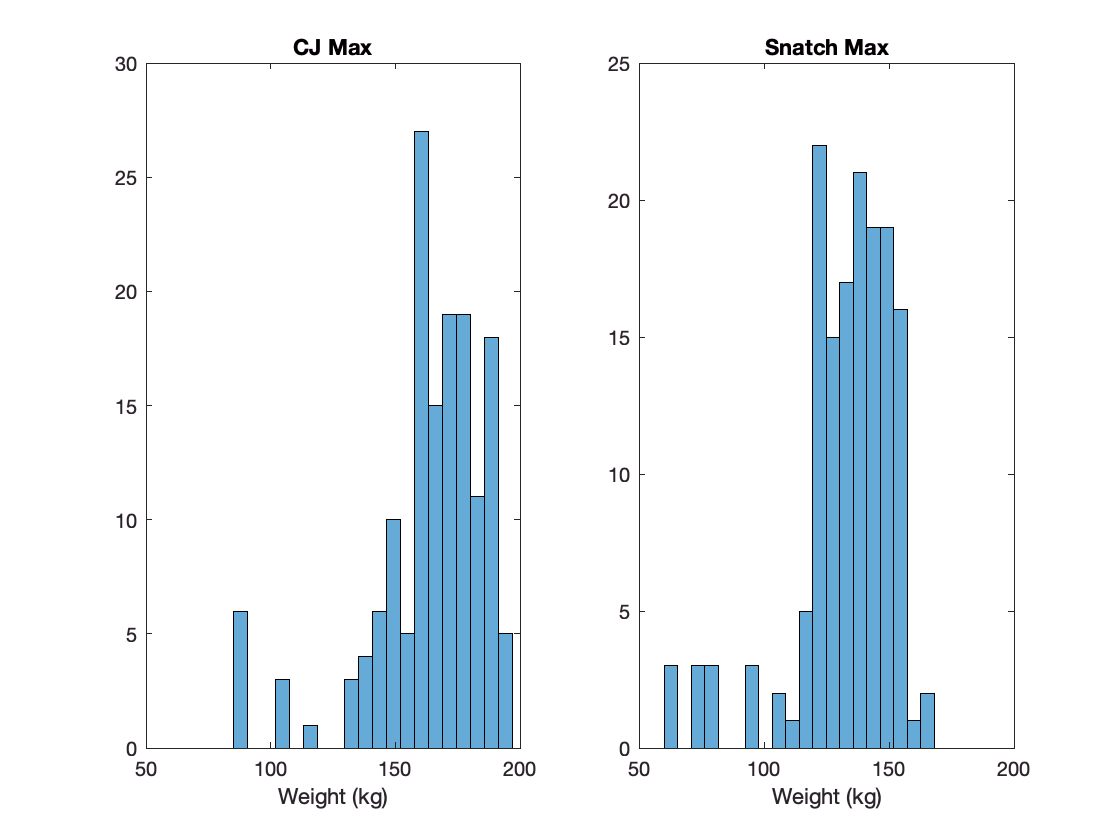

% Generate CJ max and snatch max histograms
figure
subplot(1,2,1)
histogram(cj_max,20)
title('CJ Max')
xlabel('Weight (kg)')
subplot(1,2,2)
histogram(snatch_max,20)
title('Snatch Max')
xlabel('Weight (kg)')

## Revised Model - body weight, snatch ratio

mdl2 = fitlm([bweight, snatch_ratio],total,'VarNames',{'bweight','snatch_max/cj_max','total'}) 

mdl2 = 
Linear regression model:
    total ~ 1 + bweight + snatch_max/cj_max

Estimated Coefficients:
                         Estimate      SE       tStat       pValue  
                         ________    ______    _______    __________

    (Intercept)          -1167.3     321.28    -3.6333    0.00038446
    bweight               15.221     4.2439     3.5866    0.00045363
    snatch_max/cj_max     448.81     87.964     5.1022    1.0076e-06


Number of observations: 152, Error degrees of freedom: 149
Root Mean Squared Error: 39.4
R-squared: 0.194,  Adjusted R-Squared 0.183
F-statistic vs. constant model: 17.9, p-value = 1.06e-07


% Generate the confidence interterval for the model
coefCI(mdl2)

ans =    1.0e+03 *

   -1.8021   -0.5324
    0.0068    0.0236
    0.2750    0.6226


## Revised Model: Residuals

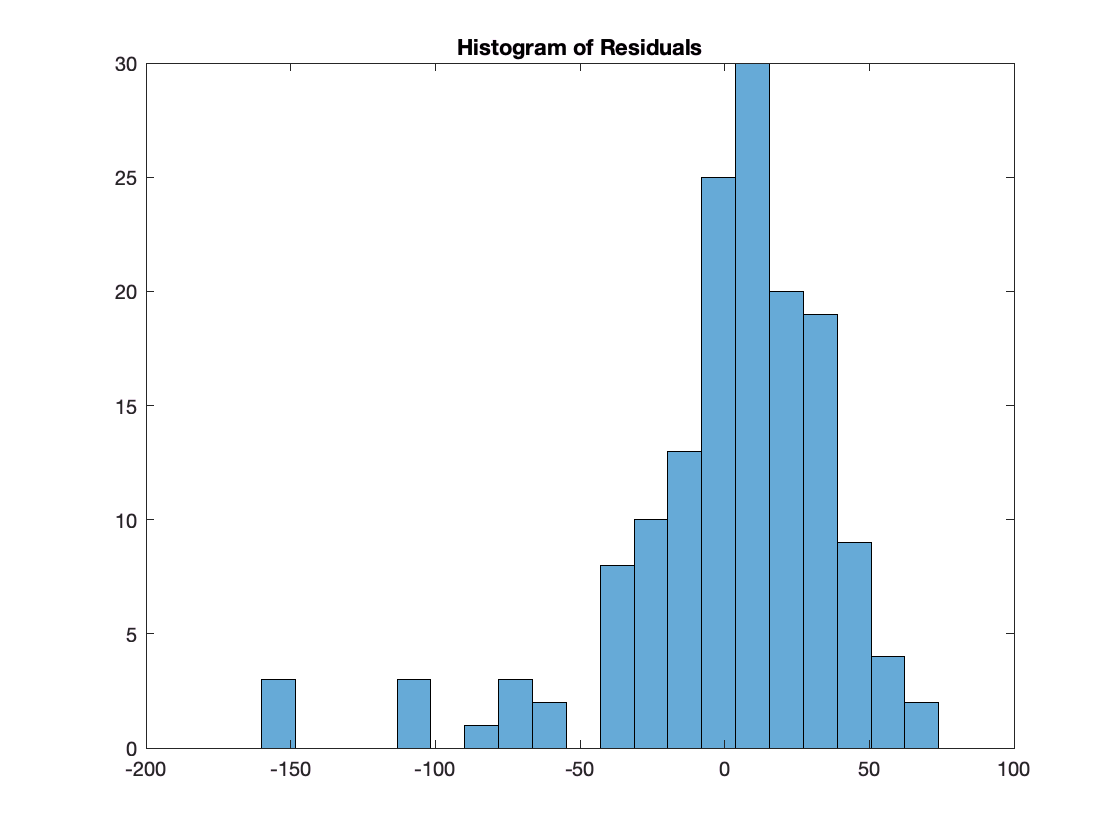

% Generate plot raw residuals 
r2 = mdl2.Residuals.Raw;
figure
histogram(r2,20)
title('Histogram of Residuals')

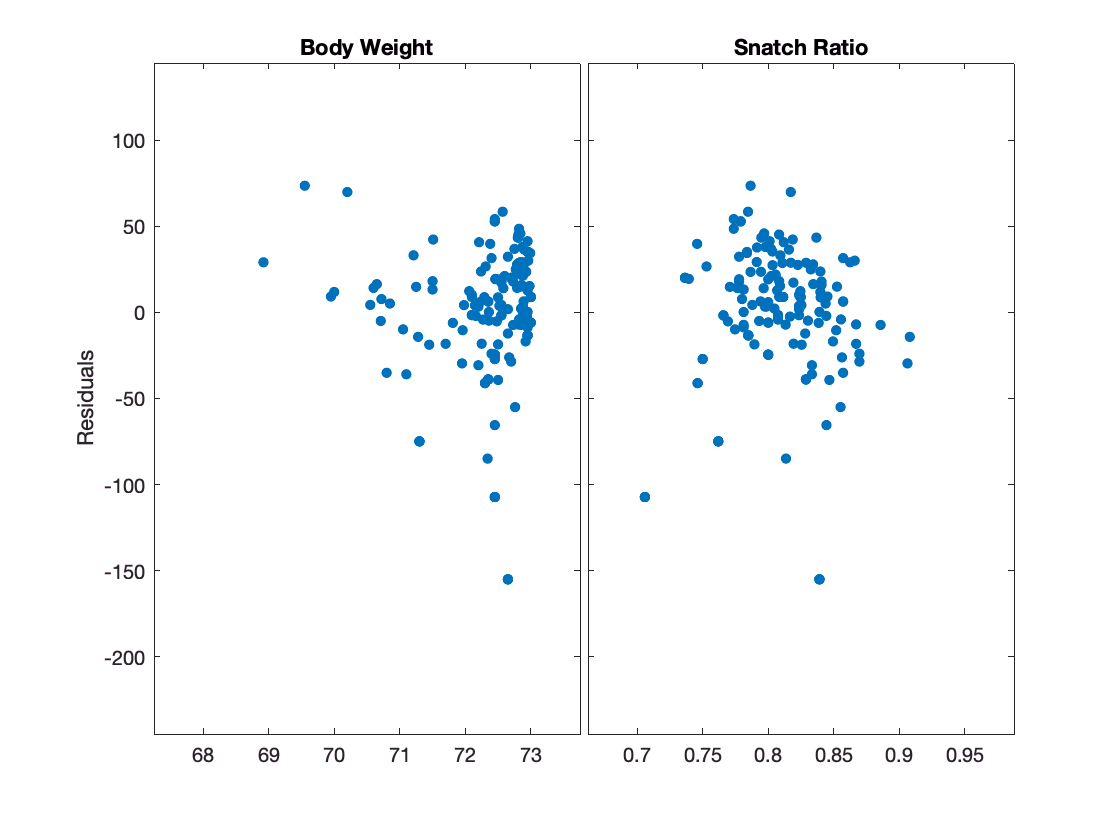


% Generate residual plot for Xs 
figure
[~,ax] = plotmatrix([bweight, snatch_max./cj_max],r2);
titles = {'Body Weight' 'Snatch Ratio'};
for i = 1:length(titles)
    title(ax(i), titles(i))
    ylabel(ax(i),'Residuals')
end

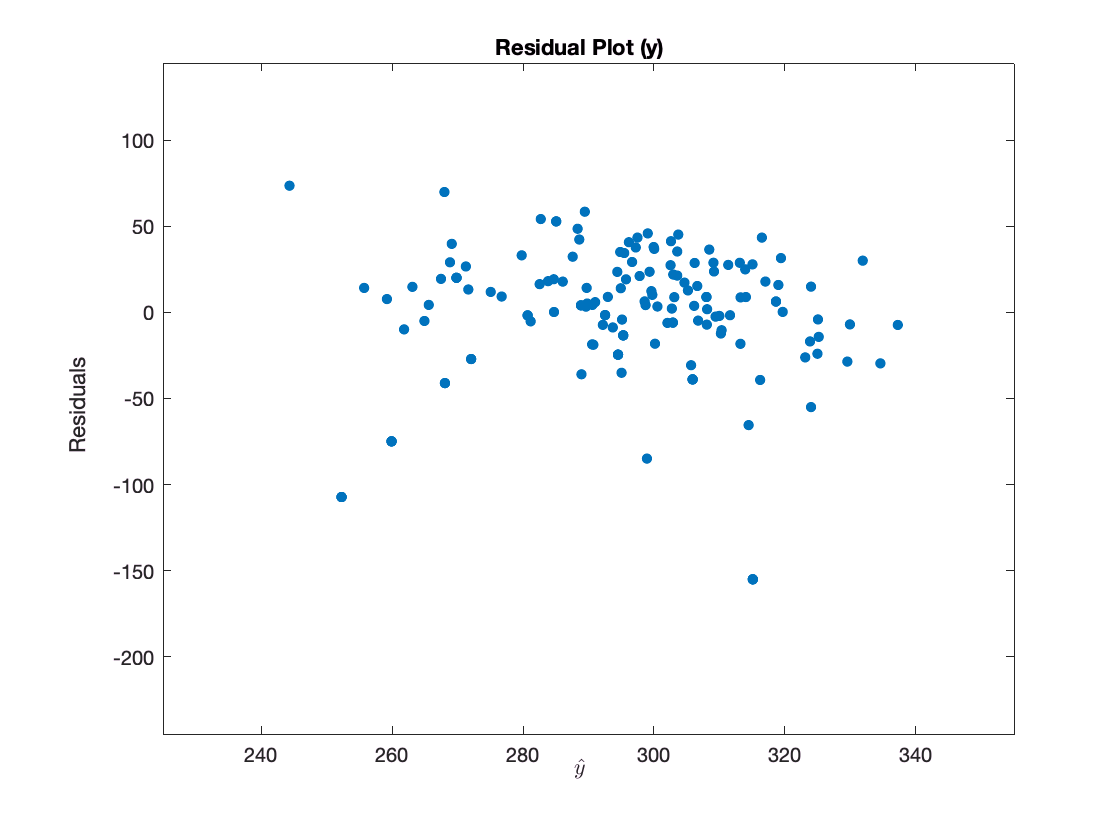


% Generate residual plot for output
figure
yhat = mdl2.Fitted;
plotmatrix(yhat,r2)
title('Residual Plot (y)')
ylabel('Residuals')
xlabel('$$\hat{y}$$', 'Interpreter', 'Latex');

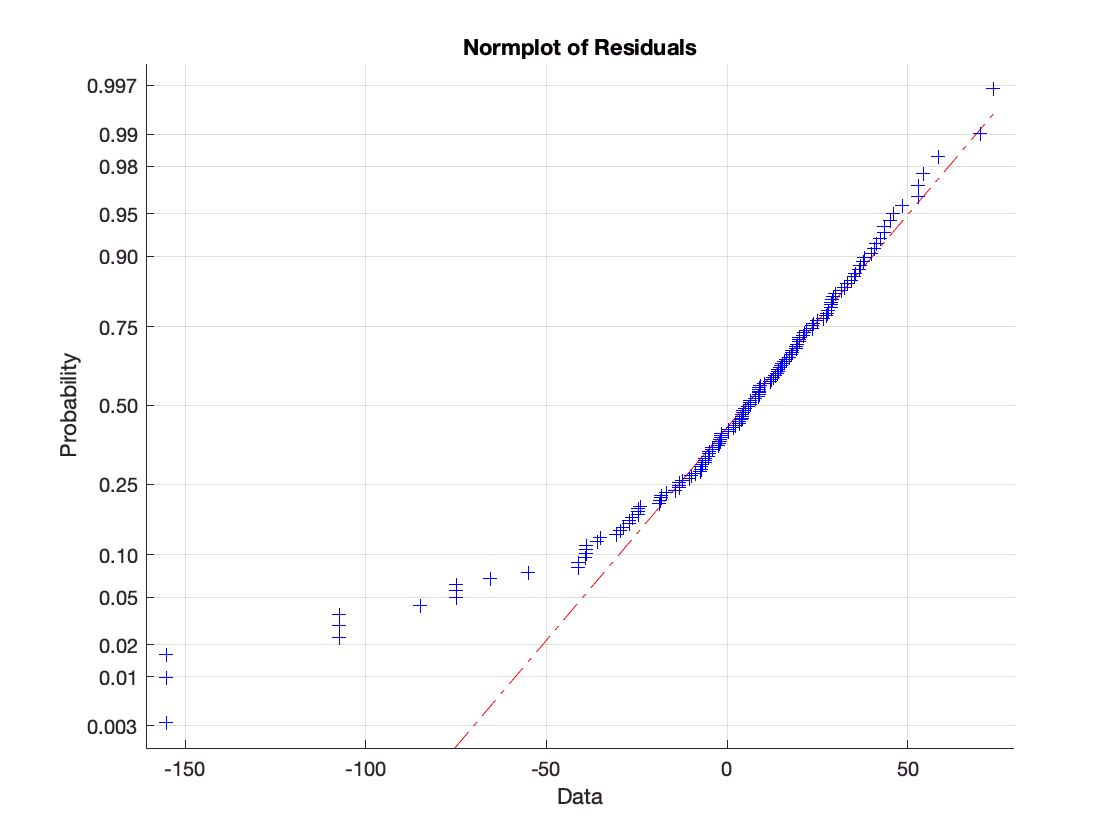


% Generate norm plot of residuals for analyzing
% (Helpful for identifying heavy-tail vs light-tail distributions)
figure
normplot(r2)
title('Normplot of Residuals')

figure

## Revised Model: Plot

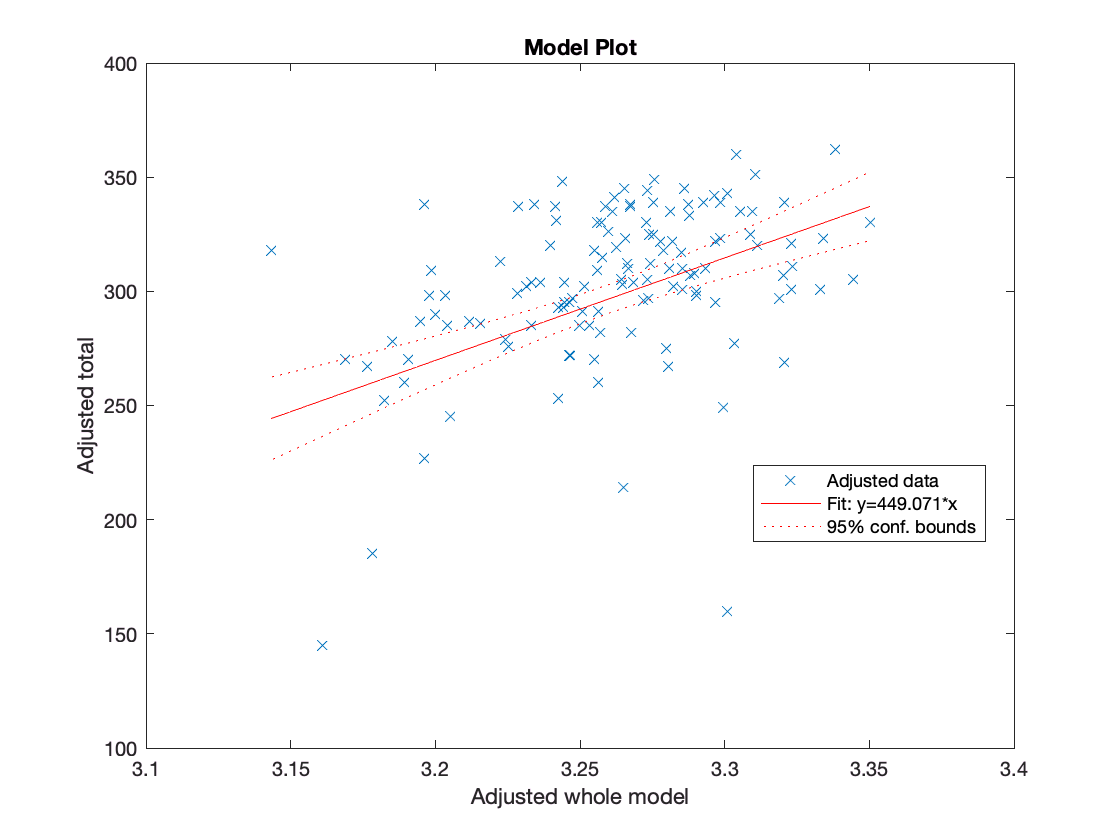

% Generate model plot (fitted line)
plot(mdl2)
title('Model Plot')